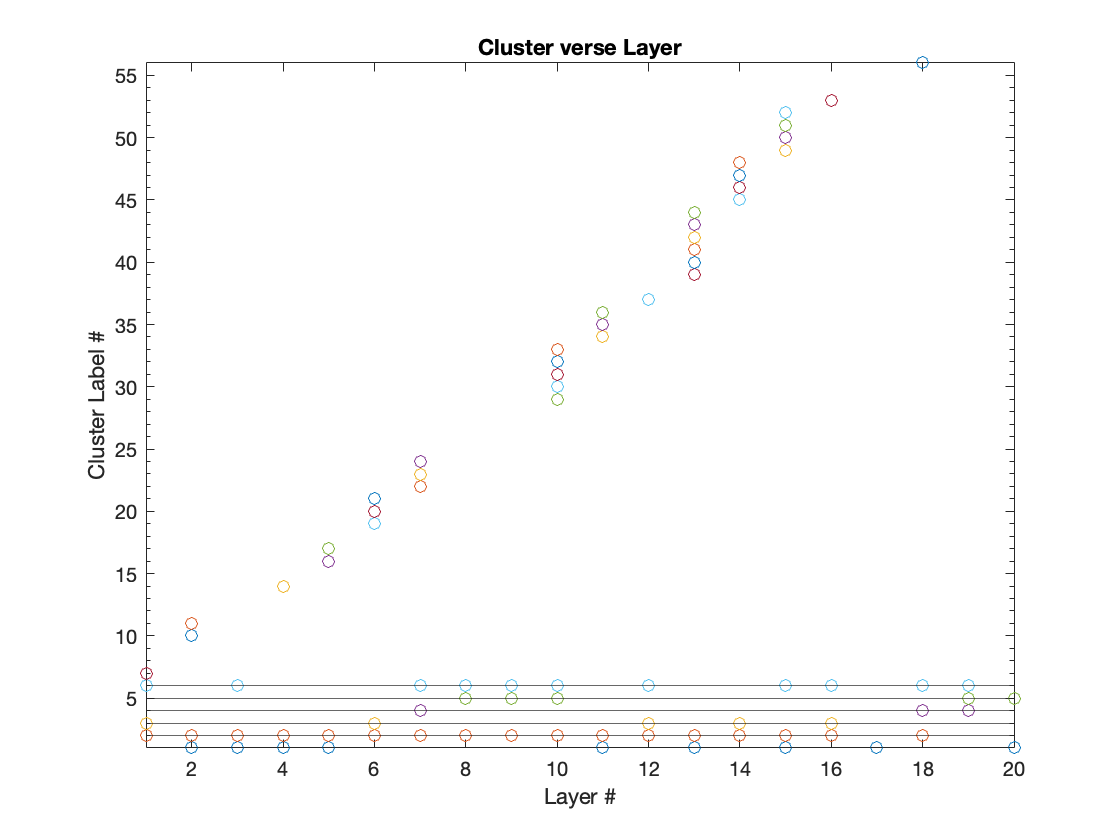

%Finding out what clusters belong to which layers

load("findK_eg21_d5_k6.mat", "kc","k","kp", "Z");

Al = importdata("theta_theta_all.mat");

load("notFixed_eg2_d5_k6.mat", "ClustersSupra");


kpl=kp;
ClustersSupra = ClustersSupra; %length(unique(ClustersSupra))
k=k;

un_len = max(ClustersSupra);

colors = random_color(un_len); %fix so its not all same colors

L = 20; %20 layers
x=1;
z=64;
y=1;

clusterssupra_total = [];

cluster_layer = zeros(un_len,L);

layer_nodes_per_cluster = []; %matrix that is un_len each matrix has zeros(k_labels,64);

for i=1:un_len
    layer_nodes_per_cluster = [layer_nodes_per_cluster, {zeros(L,64)}];
end

for cindex=1:L
    
    A = Al{cindex};
   
    k_labels = unique(ClustersSupra(x:z));
    clusterssupra_total = [clusterssupra_total, {k_labels}];
   
    
    for index=1:length(k_labels)
        label = k_labels(index);
        cluster_layer(label,cindex) = 1; %mark present in layer
        new_nodes = find(ClustersSupra(x:z)==label)'; 
        
        for new=1:length(new_nodes)
            layer_nodes_per_cluster{1,label}(cindex,new_nodes(new)) = 1;
        end
        
    end

    x=x+64;
    z=(x+63);
  
end

T = array2table(cluster_layer, ...
    'VariableNames',{'Layer 1','Layer 2','Layer 3', 'Layer 4','Layer 5','Layer 6','Layer 7','Layer 8','Layer 9','Layer 10','Layer 11','Layer 12','Layer 13','Layer 14','Layer 15', 'Layer 16','Layer 17','Layer 18','Layer 19','Layer 20'});


%Plotting data stored

figure(1);

M = cluster_layer;
% Loop over rows
for i = 1:size(M, 1)
    % Find column indices where there is a 1
    ind = find(M(i,:)==1);
    
    % Plot indices against row number
    plot(ind, repmat(i, size(ind)), 'o');
    hold on;
end

% Set axis labels and limits
xlabel('Layer #');
ylabel('Cluster Label #');
xlim([1 size(M, 2)]);
ylim([1 size(M, 1)]);
title("Cluster verse Layer");
set(gca,'YMinorTick', 'on');
yline(1:6);
hold off;

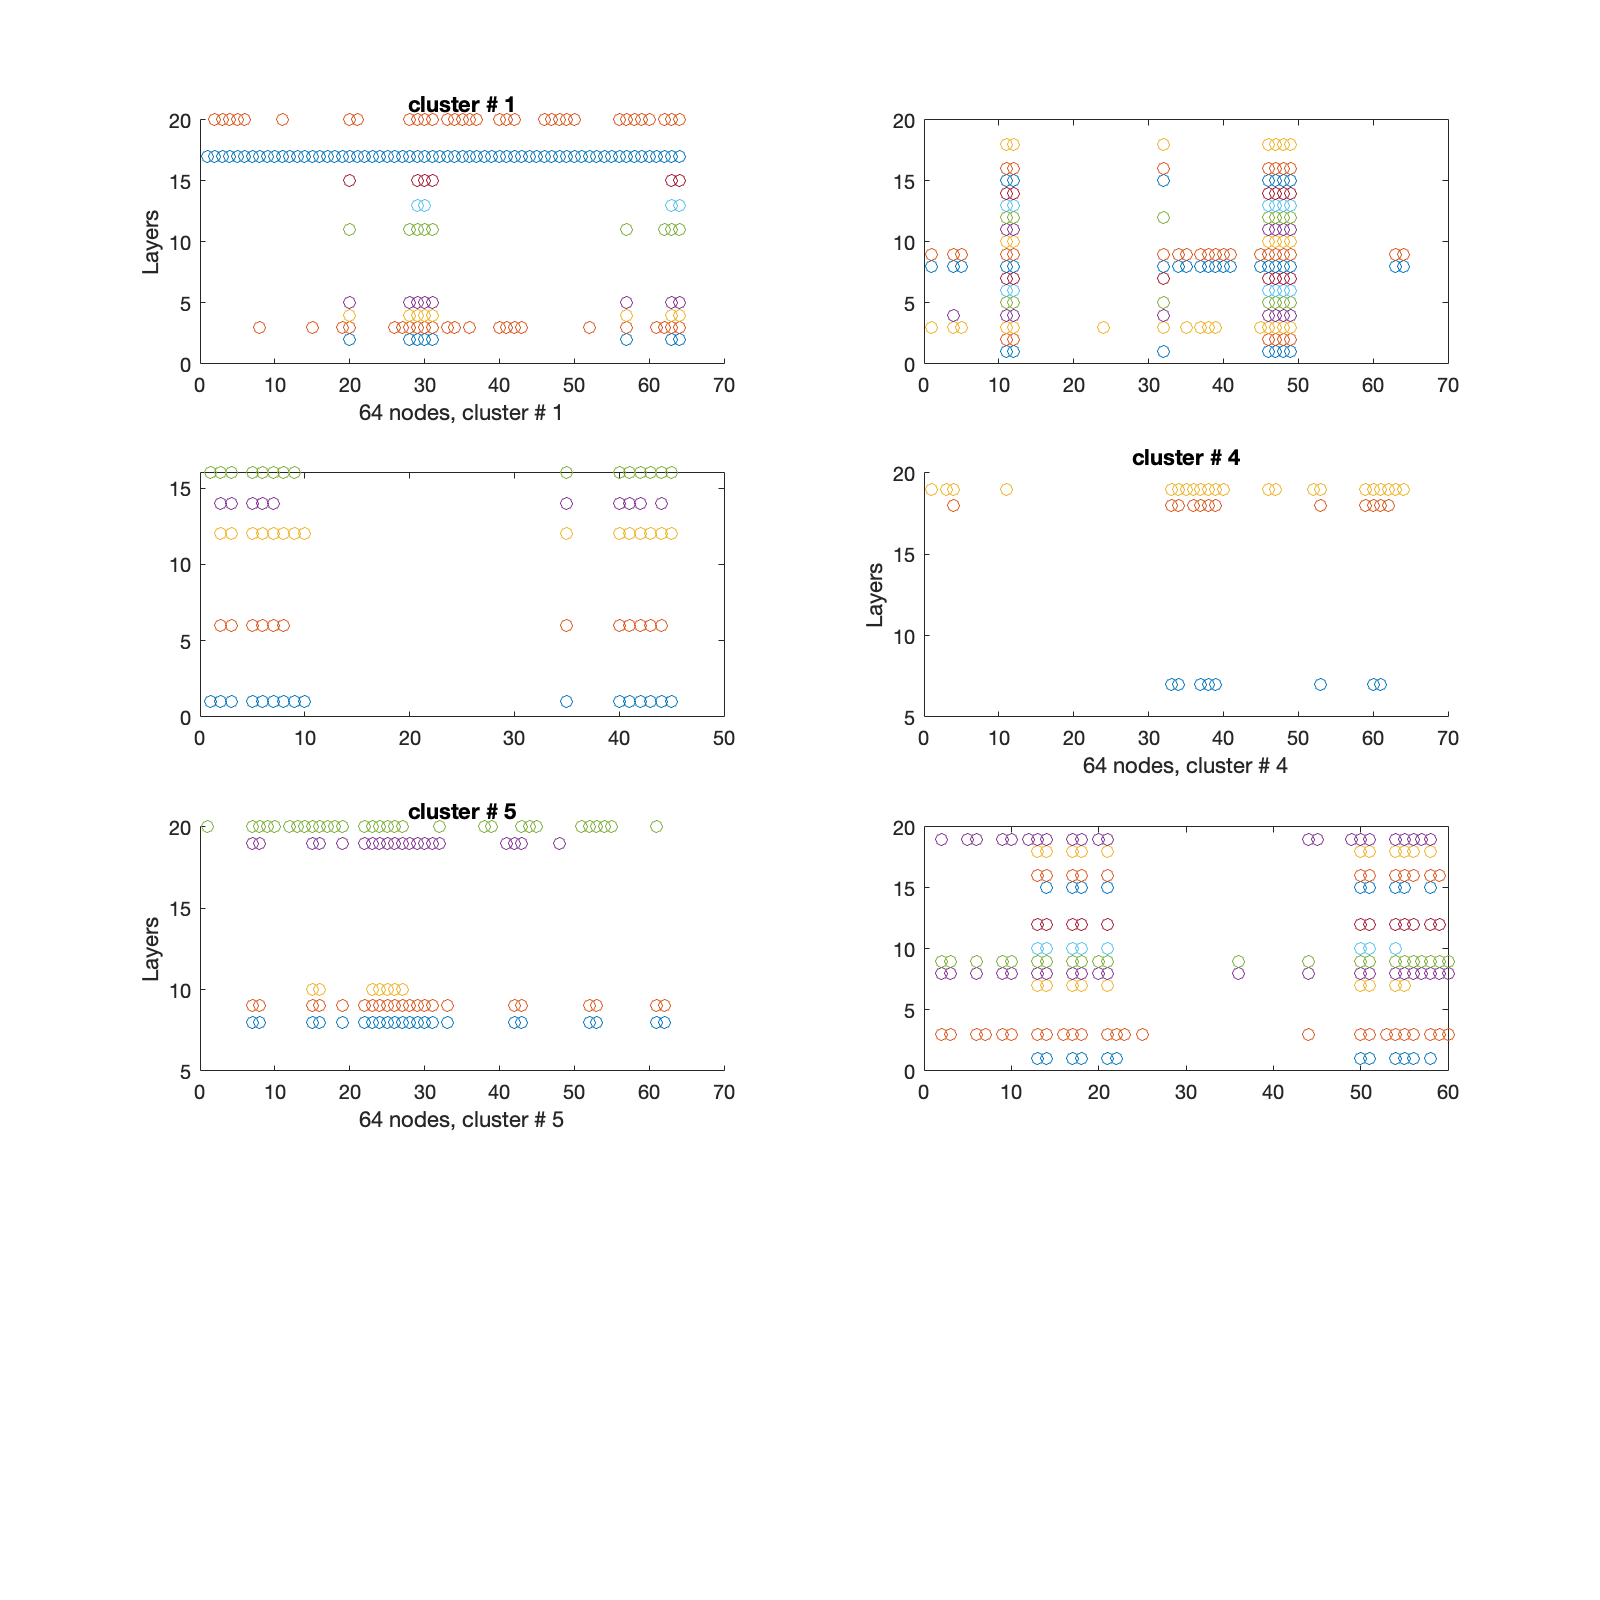




figure(2)
figure('Position', [0 0 800 800])

P= layer_nodes_per_cluster;


subplot_rows = length(P);
subplot_cols = 1;

% Loop over rows

%This graph helps identify the outliters for layers and nodes per kc
%cluster
tiledlayout(4,2)

prob_of_node_per_cluster = []; % Probability of Nodes
 
for i = 1:length(P)
    prob_of_node_per_cluster = [prob_of_node_per_cluster, {zeros(64,1)}];
    M = P{i};
    
    
     if i >= 7
         break
     end
    nexttile
     %subplot(8,1, i) % 'Position',  [0.1 0.1 0.8 0.8]) %, 'Position', [x y w h])
    % Set axis labels and limits
    title(sprintf('cluster # %d',i))
    xlabel(sprintf('64 nodes, cluster # %d',i));
    ylabel('Layers');
    for n = 1:size(M, 1)
        % Find column indices where there is a 1
        ind = find(M(n,:)==1);
        
        for in = 1:length(ind)
            prob_of_node_per_cluster{1,i}(ind(in),1) = prob_of_node_per_cluster{1,i}(ind(in),1)+1;
        end
         
        % Plot indices against row number
        plot(ind, repmat(n, size(ind)), 'o');
        hold on;
    end
    hold off;
    
    %pos = get(gcf, 'Position');
    %set(gcf, 'Position',pos+[0 -500 0 500])


end